# Learning a CNN model

Paweł Antoniuk 2021

Bialystok University of Technology

% clear; clc;
inputSize = [349, 150, 2];

inputSpecgramsFile = 'Spectrograms\specgrams-all-lin_lr.h5';
networkFileFormat = 'nets_lr/net_lr_%d';

iNetwork = 1;
currentNetwork = load(sprintf(networkFileFormat, iNetwork), 'net_lr').net_lr;

dslabels = h5read(inputSpecgramsFile, '/labels');
dsinfo = h5info(inputSpecgramsFile, '/data');
dsfilenames = h5read(inputSpecgramsFile, '/filenames');
dssz = dsinfo.Dataspace.Size(1:end-1);
dslen = dsinfo.Dataspace.Size(end);
timeValues = h5read(inputSpecgramsFile, '/axis/time');
freqValues = h5read(inputSpecgramsFile, '/axis/freq');
[songNames, HRTFs, HRTFGroups] = getSongNamesHRTFsGroups(dsfilenames);
uniqueTestSongNames = unique(songNames);
uniqueTestHRTFNames = unique(HRTFs);

Grad-CAM network explaining    

scoreMaps = zeros([dssz(1:end-1) dslen]);

for ii = 1:dslen
    input = h5read(inputSpecgramsFile, '/data', [1 1 1 ii], [dssz 1]);
    label = dslabels(ii) + 1;
    scoreMaps(:, :, ii) = gradCAM(currentNetwork, input, label);
    if mod(ii, 100) == 0
        fprintf('%d of %d\n', ii, dslen);
    end
end

100 of 22496
200 of 22496
300 of 22496
400 of 22496
500 of 22496
600 of 22496
700 of 22496
800 of 22496
900 of 22496
1000 of 22496
1100 of 22496
1200 of 22496
1300 of 22496
1400 of 22496
1500 of 22496
1600 of 22496
1700 of 22496
1800 of 22496
1900 of 22496
2000 of 22496
2100 of 22496
2200 of 22496
2300 of 22496
2400 of 22496
2500 of 22496
2600 of 22496
2700 of 22496
2800 of 22496
2900 of 22496
3000 of 22496
3100 of 22496
3200 of 22496
3300 of 22496
3400 of 22496
3500 of 22496
3600 of 22496
3700 of 22496
3800 of 22496
3900 of 22496
4000 of 22496
4100 of 22496
4200 of 22496
4300 of 22496
4400 of 22496
4500 of 22496
4600 of 22496
4700 of 22496
4800 of 22496
4900 of 22496
5000 of 22496
5100 of 22496
5200 of 22496
5300 of 22496
5400 of 22496
5500 of 22496
5600 of 22496
5700 of 22496
5800 of 22496
5900 of 22496
6000 of 22496
6100 of 22496
6200 of 22496
6300 of 22496
6400 of 22496
6500 of 22496
6600 of 22496
6700 of 22496
6800 of 22496
6900 of 22496
7000 of 22496
7100 of 22496
7200 of 22496
7

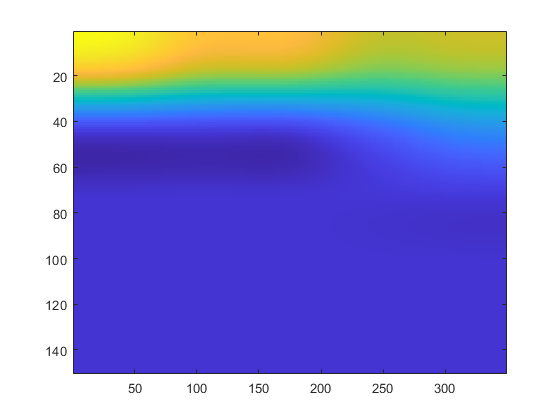

clf
imagesc(scoreMaps(:, :, end-1)');

Split score maps into positive and negatives

positiveNegativeScoreMaps = zeros([dssz(1:end-1) dslen/2 2]);
iPosScoreMap = 1;
iNegScoreMap = 1;

for ii = 1:dslen
    if dslabels(ii) == 0
        positiveNegativeScoreMaps(:, :, iPosScoreMap, 1) = scoreMaps(:, :, ii);
        iPosScoreMap = iPosScoreMap + 1;
    elseif dslabels(ii) == 1
        positiveNegativeScoreMaps(:, :, iNegScoreMap, 2) = scoreMaps(:, :, ii);
        iNegScoreMap = iNegScoreMap + 1;
    else
        error(['Wrong label ' num2str(dslabels(ii)) ' for ' num2str(ii)]);
    end
end

Split score maps by HRTF

scoreMapsPosByHRTF = cell(size(uniqueTestHRTFNames));
scoreMapsNegByHRTF = cell(size(uniqueTestHRTFNames));

for ii = 1:dslen
    filename = dsfilenames(ii);
    fParts = strsplit(filename, '_');
    fHRTF = fParts{2};
    iHRTF = find(strcmp(uniqueTestHRTFNames, fHRTF));
	
	if dslabels(ii) == 0
		scoreMapsPosByHRTF{iHRTF} = cat(3, scoreMapsPosByHRTF{iHRTF}, scoreMaps(:, :, ii));
    elseif dslabels(ii) == 1
		scoreMapsNegByHRTF{iHRTF} = cat(3, scoreMapsNegByHRTF{iHRTF}, scoreMaps(:, :, ii));
    else
        error(['Wrong label ' num2str(dslabels(ii)) ' for ' num2str(ii)]);
	end    
end

Split score maps by song name

scoreMapsPosBySongName = cell(size(uniqueTestSongNames));
scoreMapsNegBySongName = cell(size(uniqueTestSongNames));

for ii = 1:dslen
    filename = dsfilenames(ii);
    fParts = strsplit(filename, '_');
    fSongName = fParts{1};
    iSongName = find(strcmp(uniqueTestSongNames, fSongName));
	
	if dslabels(ii) == 0
		scoreMapsPosBySongName{iSongName} = cat(3, scoreMapsPosBySongName{iSongName}, scoreMaps(:, :, ii));
    elseif dslabels(ii) == 1
		scoreMapsNegBySongName{iSongName} = cat(3, scoreMapsNegBySongName{iSongName}, scoreMaps(:, :, ii));
    else
        error(['Wrong label ' num2str(dslabels(ii)) ' for ' num2str(ii)]);
	end    
end

Display average score maps

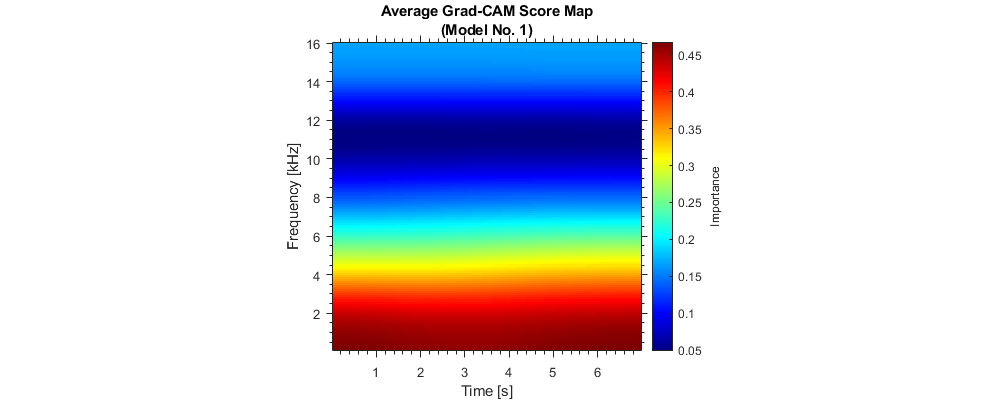

figure('Position', [0 0 1000 400])
meanScoreMap = mean(scoreMaps(:, :, :), 3);
imagesc(timeValues, freqValues / 1000, meanScoreMap');
colormap jet; 
axis xy;  
pbaspect([1 1 1]);
title({'Average Grad-CAM Score Map', sprintf('(Model No. %d)', iNetwork)});
xlabel('Time [s]');
ylabel('Frequency [kHz]');
ylabel(colorbar, 'Importance');
set(gca, 'XMinorTick', 'on', 'YMinorTick', 'on', 'TickDir', 'out', 'TickLength', [0.02 0.025])

save(sprintf('gradCAM_meanScoreMap_%d', iNetwork), 'meanScoreMap', '-v7.3');

Display average score maps by label

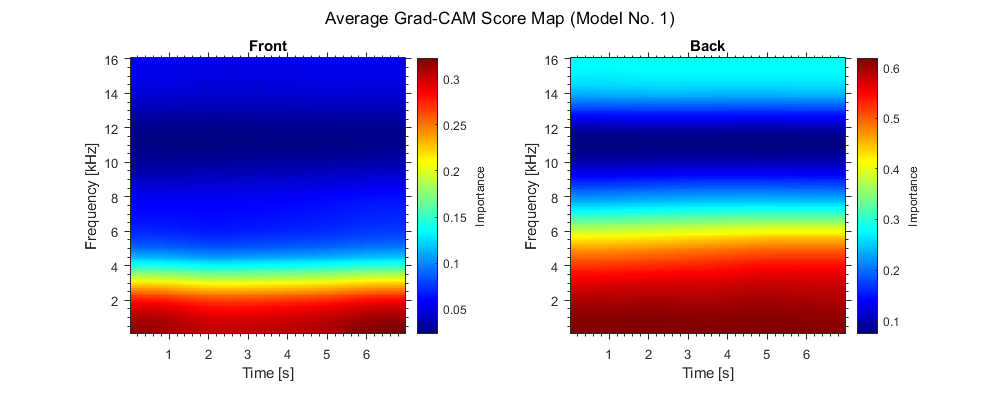

figure('Position', [0 0 1000 400])
imageNames = {'Front', 'Back'};
for ii = 1:2
    subplot(1, 2, ii);
    meanScoreMap = mean(positiveNegativeScoreMaps(:, :, :, ii), 3);
    imagesc(timeValues, freqValues / 1000, meanScoreMap');
    colormap jet; 
    axis xy;  
    pbaspect([1 1 1]);
    title(imageNames{ii});
    xlabel('Time [s]');
    ylabel('Frequency [kHz]');
    ylabel(colorbar, 'Importance');
	set(gca, 'XMinorTick', 'on', 'YMinorTick', 'on', 'TickDir', 'out', 'TickLength', [0.02 0.025])
    save(sprintf('gradCAM_meanScoreMap_pn%d_%d', ii, iNetwork), 'meanScoreMap', '-v7.3');
end
sgtitle(sprintf('Average Grad-CAM Score Map (Model No. %d)', iNetwork));

Display average score maps by HRTF

for ii = 1:length(scoreMapsPosByHRTF)
    if mod(ii - 1, 16) == 0
        figure('Position', [0 0 1000 1000]);
        sgtitle({sprintf('Average Grad-CAM Score Maps - front scene (%d of %d)', ...
            ceil(ii / 16), ceil(length(scoreMapsPosByHRTF) / 16)), sprintf('(Model No. %d)', iNetwork)});
    end
    subplot(4, 4, mod(ii - 1, 16) + 1);
    scoreMap = scoreMapsPosByHRTF{ii};
    meanScoreMap = mean(scoreMap, 3);
    imagesc(timeValues, freqValues / 1000, meanScoreMap');
%     axis image
    colormap jet; 
    axis xy;  
    pbaspect([1 1 1]);
    title(['' uniqueTestHRTFNames{ii}]);
    xlabel('Time [s]');
    ylabel('Frequency [kHz]');
    ylabel(colorbar, 'Importance');
	set(gca, 'XMinorTick', 'on', 'YMinorTick', 'on', 'TickDir', 'out', 'TickLength', [0.02 0.025])
    save(sprintf('gradCAM_meanScoreMap_hrtf_p%d_%d', ii, iNetwork), 'meanScoreMap', '-v7.3');
end



for ii = 1:length(scoreMapsNegByHRTF)
    if mod(ii - 1, 16) == 0
        figure('Position', [0 0 1000 1000]);
        sgtitle({sprintf('Average Grad-CAM Score Maps - back scene (%d of %d)', ...
            ceil(ii / 16), ceil(length(scoreMapsNegByHRTF) / 16)), sprintf('(Model No. %d)', iNetwork)});
    end
    subplot(4, 4, mod(ii - 1, 16) + 1);
    scoreMap = scoreMapsNegByHRTF{ii};
    meanScoreMap = mean(scoreMap, 3);
    imagesc(timeValues, freqValues / 1000, meanScoreMap');
%     axis image
    colormap jet; 
    axis xy;  
    pbaspect([1 1 1]);
    title(['' uniqueTestHRTFNames{ii}]);
    xlabel('Time [s]');
    ylabel('Frequency [kHz]');
    ylabel(colorbar, 'Importance');
	set(gca, 'XMinorTick', 'on', 'YMinorTick', 'on', 'TickDir', 'out', 'TickLength', [0.02 0.025])
    save(sprintf('gradCAM_meanScoreMap_hrtf_n%d_%d', ii, iNetwork), 'meanScoreMap', '-v7.3');
end

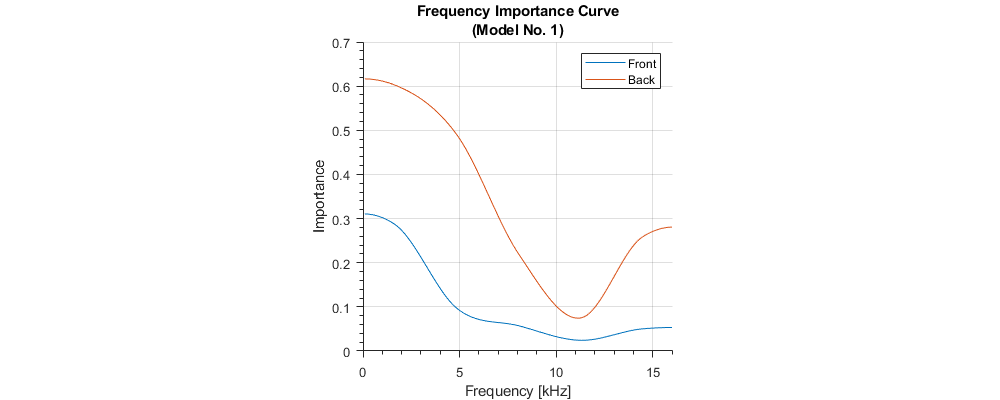

figure('Position', [0 0 1000 400])
hold on
for ii = 1:2
    meanSpectrum = mean(positiveNegativeScoreMaps(:, :, :, ii), [3, 1]);
%     subplot(1, 2, ii);
    plot(freqValues / 1000, meanSpectrum);
    save(sprintf('gradCAM_importance_curve_%d_%d', ii, iNetwork), 'meanSpectrum', '-v7.3');
end
title({'Frequency Importance Curve', sprintf('(Model No. %d)', iNetwork)});
pbaspect([1 1 1]);
ylabel('Importance');
xlabel('Frequency [kHz]');
legend(imageNames, 'Location','northeast');
set(gca, 'XMinorTick', 'on', 'YMinorTick', 'on', 'TickDir', 'out', 'TickLength', [0.02 0.025])
grid on
hold off

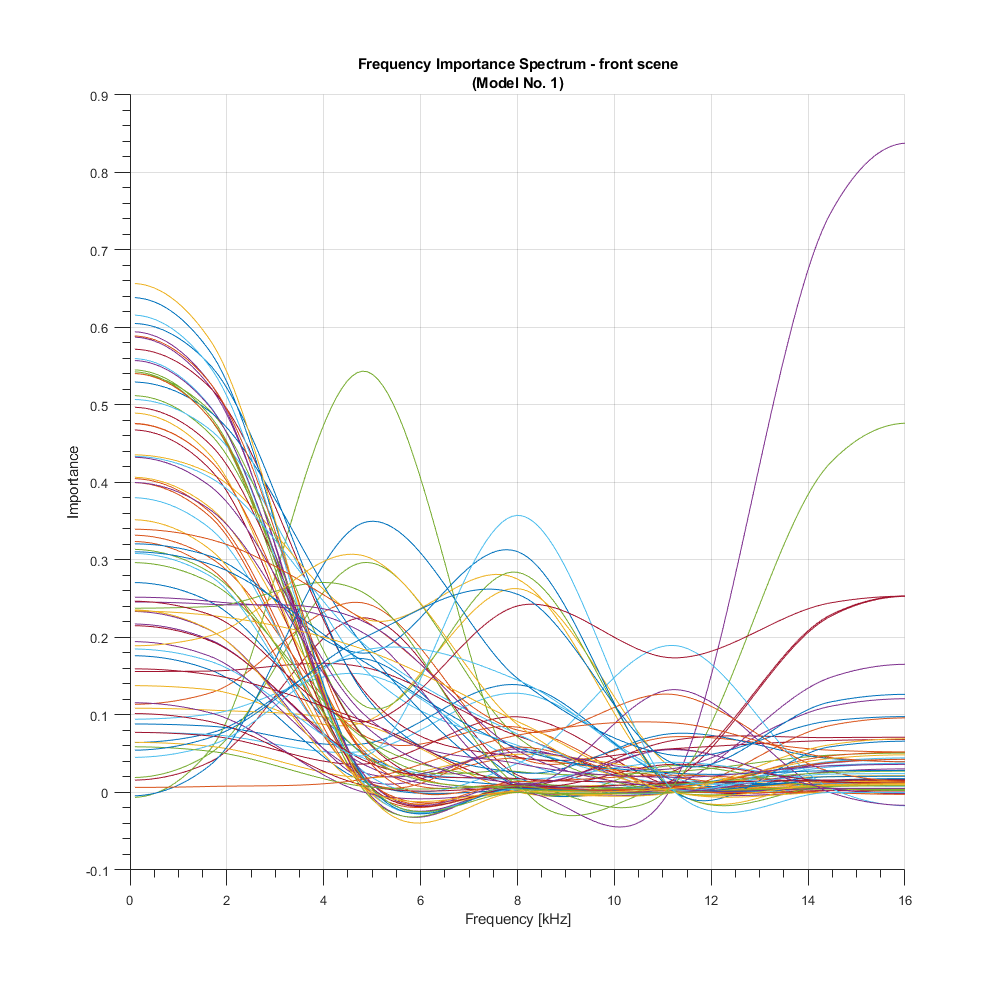

figure('Position', [0 0 1000 1000])
hold on
for ii = 1:length(scoreMapsPosByHRTF)
    scoreMap = scoreMapsPosByHRTF{ii};
    meanSpectrum = mean(scoreMap, [3, 1]);
    plot(freqValues / 1000, meanSpectrum);
    save(sprintf('gradCAM_importance_curve_hrtf_p%d_%d', ii, iNetwork), 'meanSpectrum', '-v7.3');
end
title({'Frequency Importance Spectrum - front scene', sprintf('(Model No. %d)', iNetwork)});
pbaspect([1 1 1]);
ylabel('Importance');
xlabel('Frequency [kHz]');
set(gca, 'XMinorTick', 'on', 'YMinorTick', 'on', 'TickDir', 'out', 'TickLength', [0.02 0.025])
grid on
hold off

% lgd = legend(uniqueTestHRTFNames);

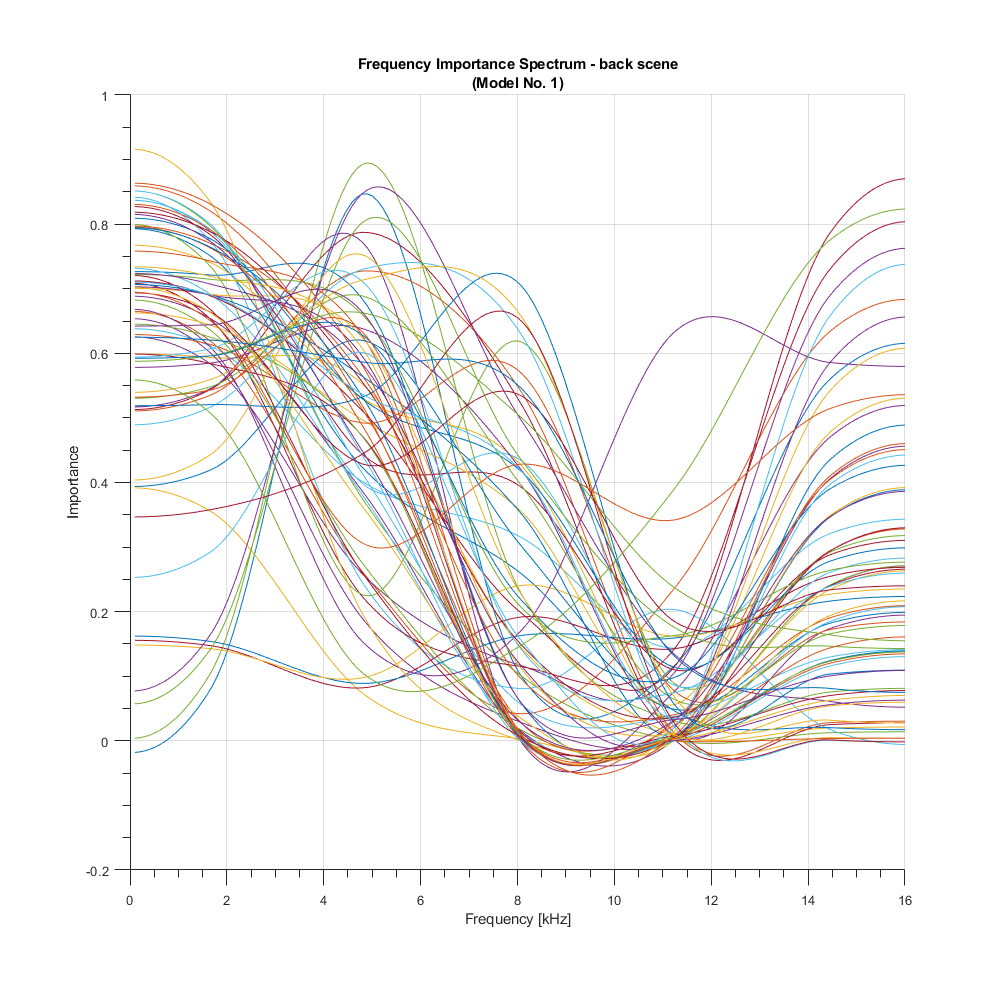

figure('Position', [0 0 1000 1000])
hold on
for ii = 1:length(scoreMapsNegByHRTF)
    scoreMap = scoreMapsNegByHRTF{ii};
    meanSpectrum = mean(scoreMap, [3, 1]);
    plot(freqValues / 1000, meanSpectrum);
    save(sprintf('gradCAM_importance_curve_hrtf_n%d_%d', ii, iNetwork), 'meanSpectrum', '-v7.3');
end
title({'Frequency Importance Spectrum - back scene', sprintf('(Model No. %d)', iNetwork)});
pbaspect([1 1 1]);
ylabel('Importance');
xlabel('Frequency [kHz]');
set(gca, 'XMinorTick', 'on', 'YMinorTick', 'on', 'TickDir', 'out', 'TickLength', [0.02 0.025])
grid on
hold off

% lgd = legend(uniqueTestHRTFNames);

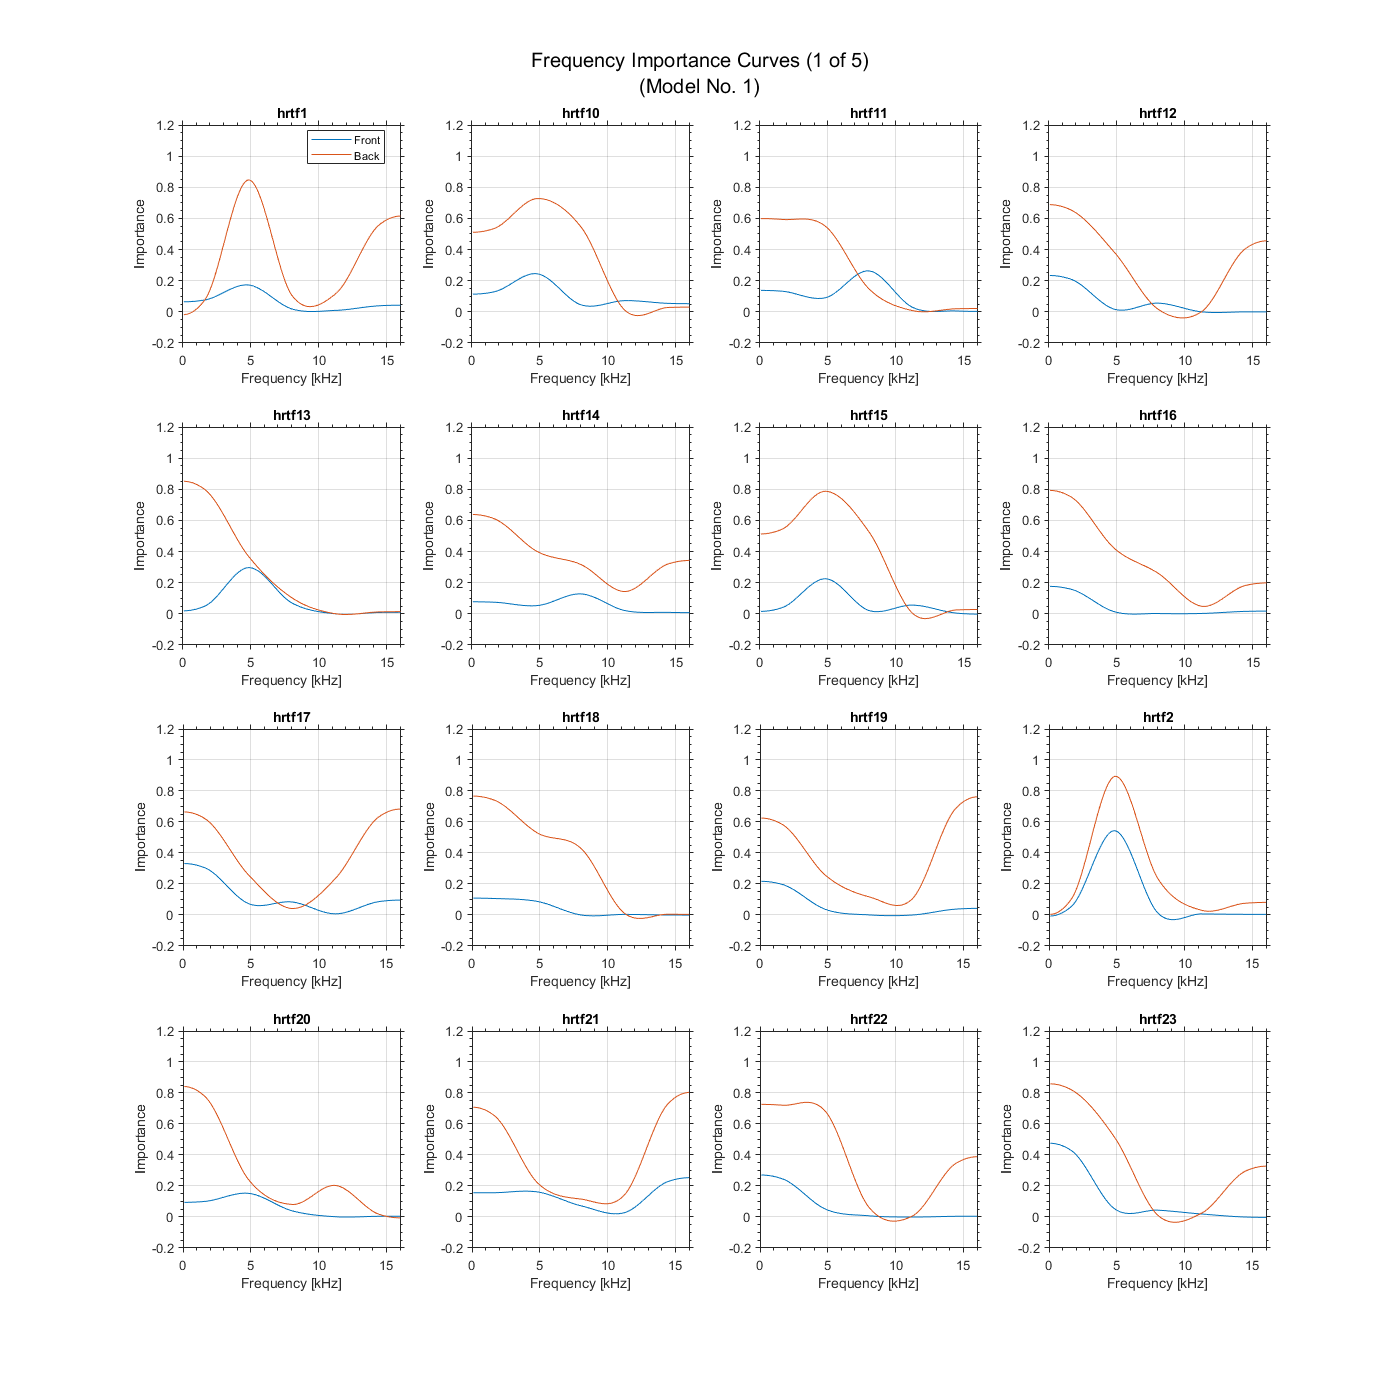

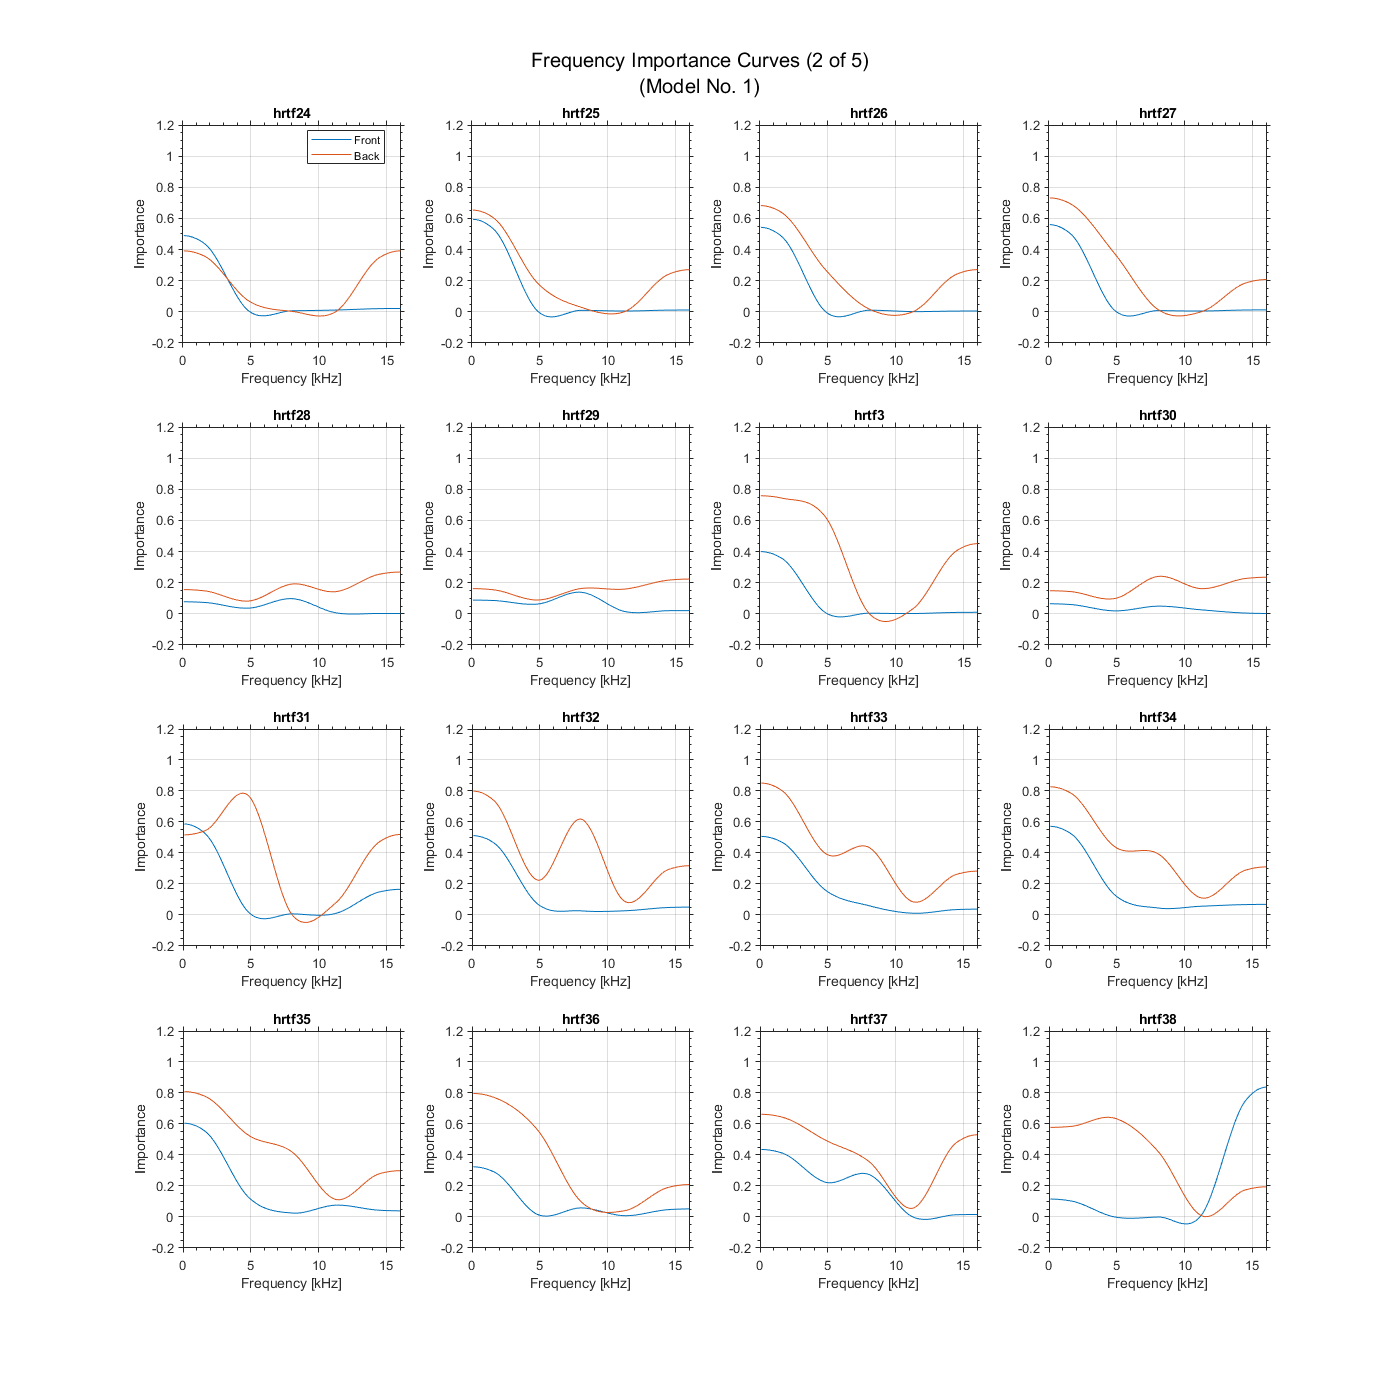

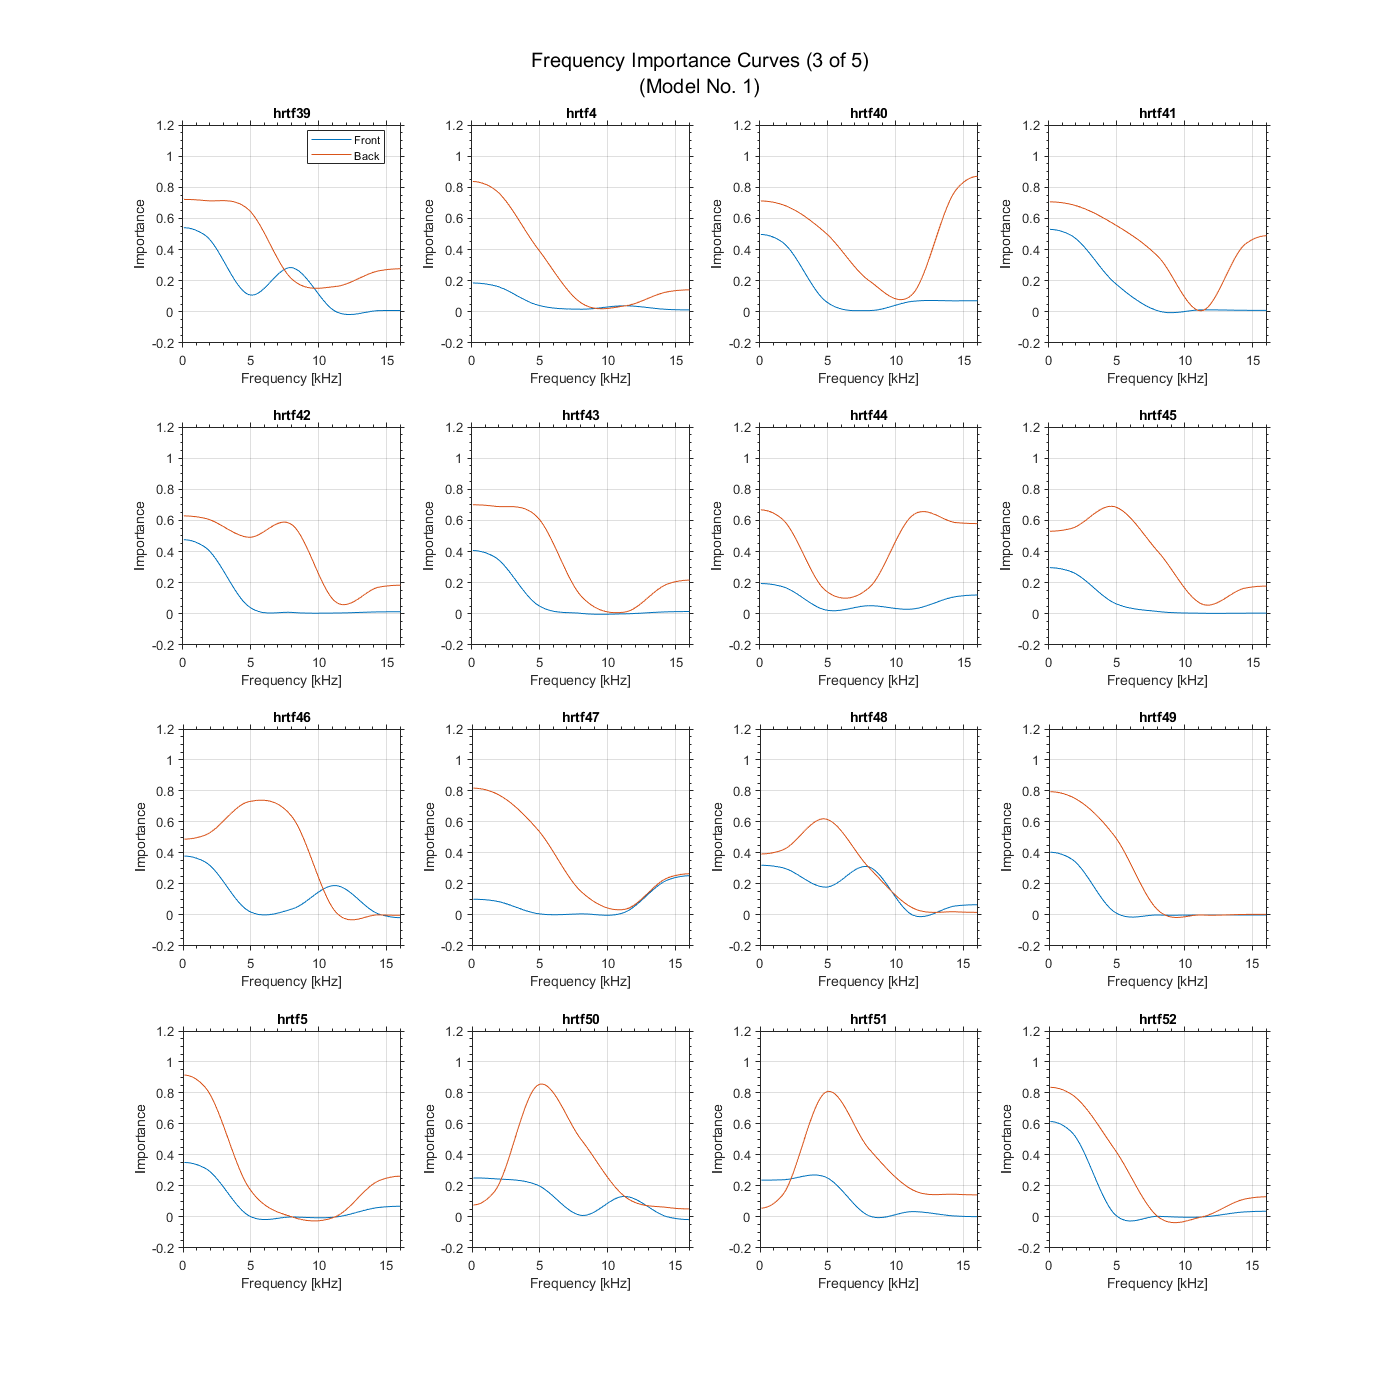

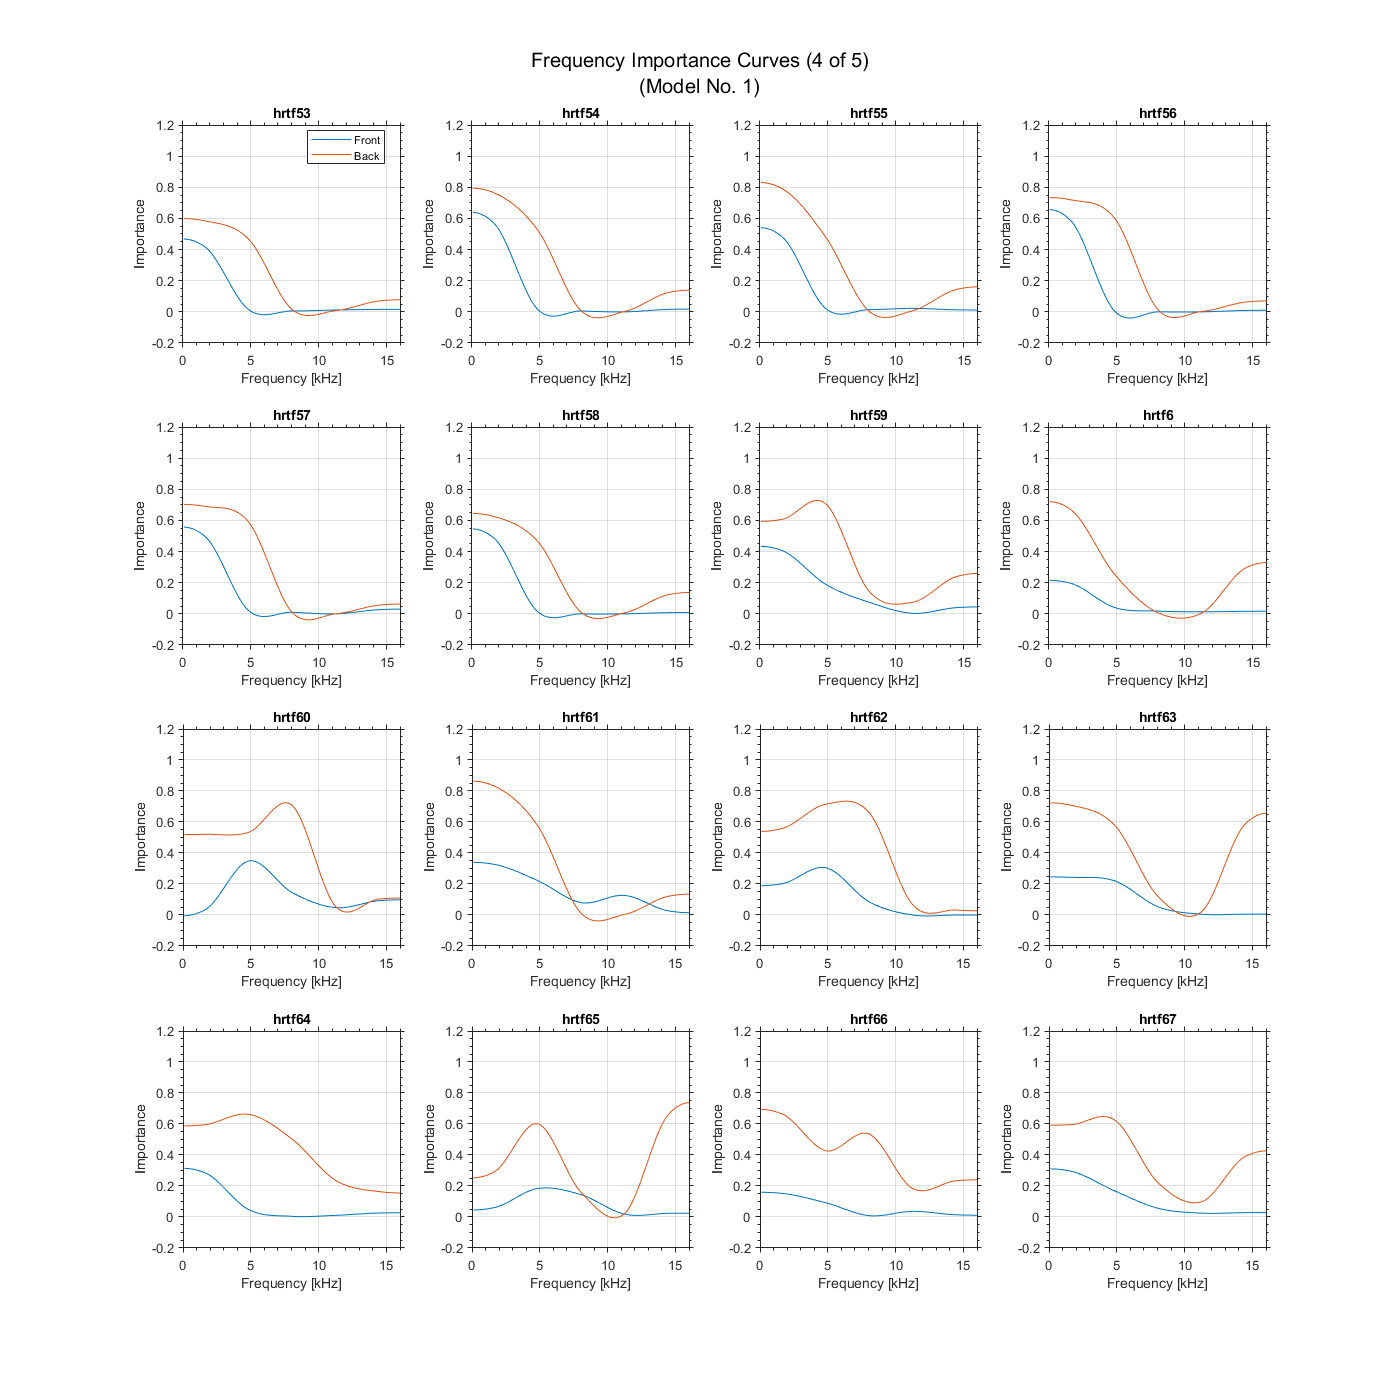

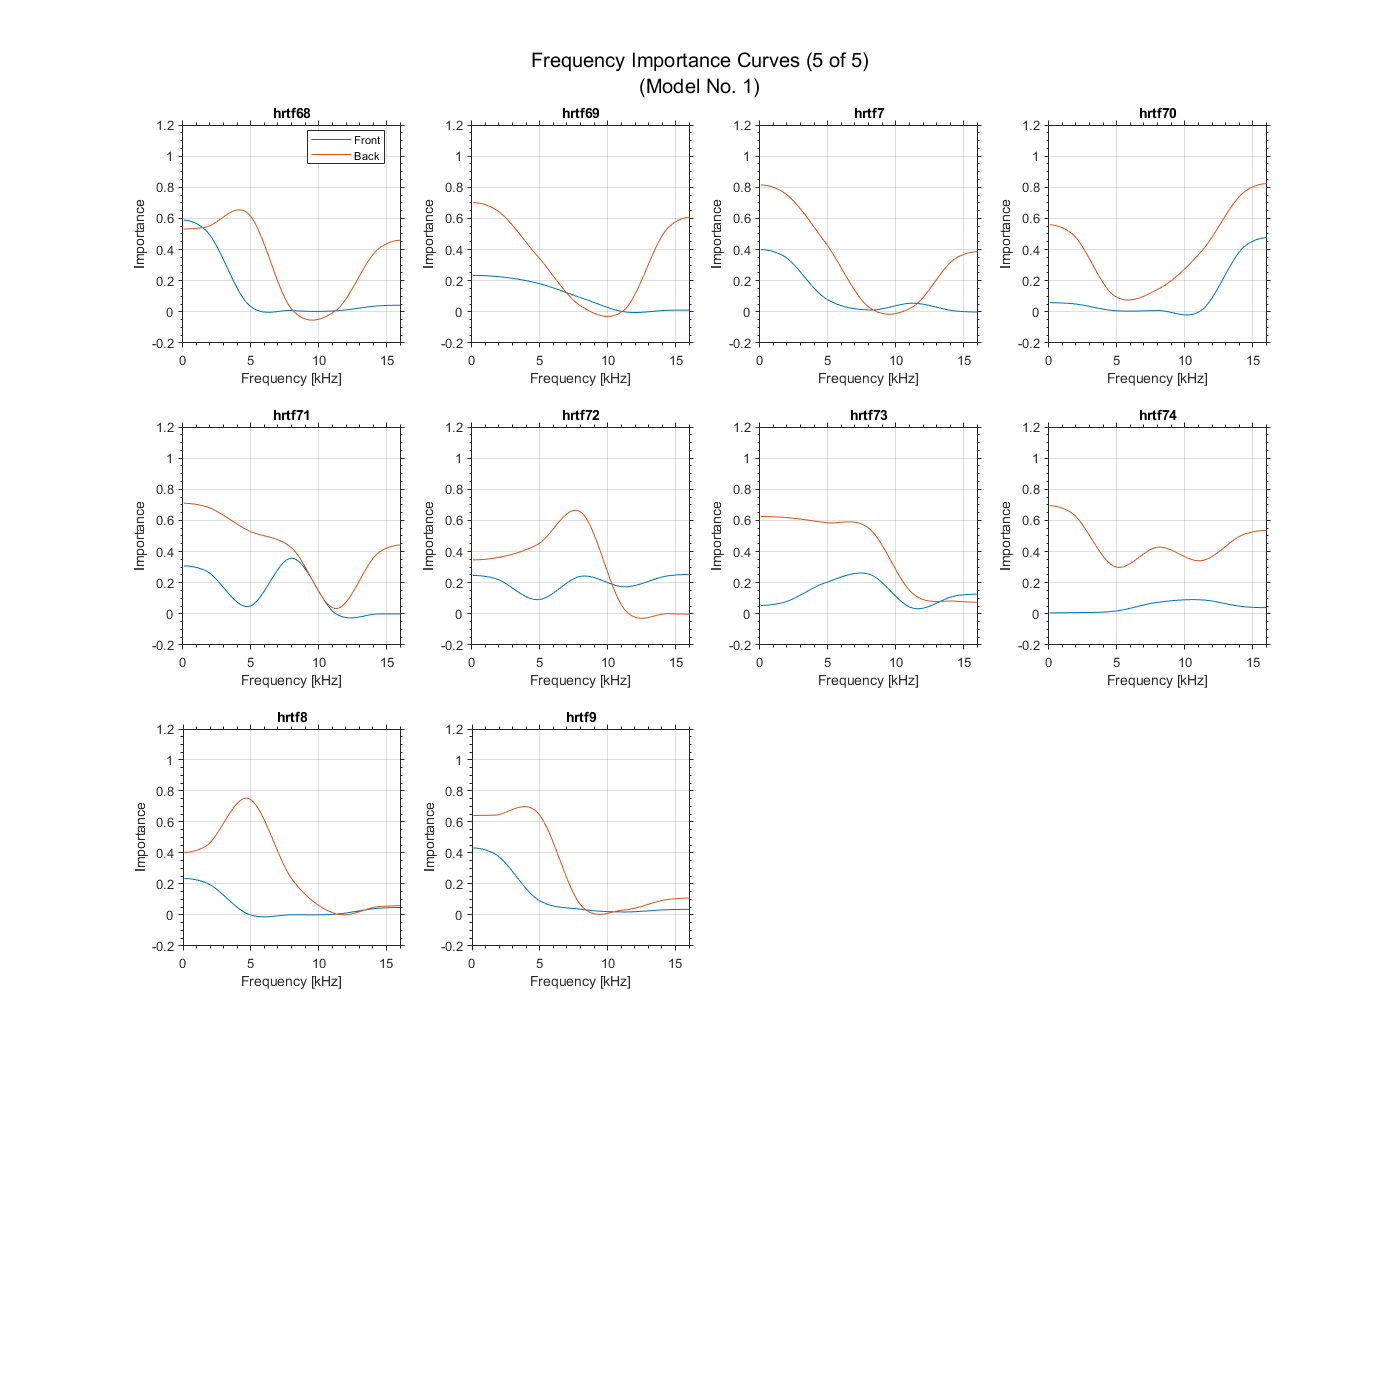

figure('Position', [0 0 1400 1400])
for ii = 1:length(scoreMapsPosByHRTF)
    if mod(ii - 1, 16) == 0
        figure('Position', [0 0 1400 1400]);
        sgtitle({sprintf('Frequency Importance Curves (%d of %d)', ...
            ceil(ii / 16), ceil(length(scoreMapsPosByHRTF) / 16)), ...
            sprintf('(Model No. %d)', iNetwork)});		
    end
    subplot(4, 4, mod(ii - 1, 16) + 1);
	
    meanSpectrum = mean(scoreMapsPosByHRTF{ii}, [3, 1]);
    plot(freqValues / 1000, meanSpectrum);
    title(uniqueTestHRTFNames{ii});
    pbaspect([1 1 1]);
    ylabel('Importance');
    xlabel('Frequency [kHz]');
	set(gca, 'XMinorTick', 'on', 'YMinorTick', 'on', 'TickDir', 'out', 'TickLength', [0.02 0.025])
	ylim([-0.2 1.2]);
	grid on
    
      save(sprintf('gradCAM_importance_curve2_hrtf_p%d_%d', ii, iNetwork), 'meanSpectrum', '-v7.3');
	
	hold on
	meanSpectrum = mean(scoreMapsNegByHRTF{ii}, [3, 1]);
    plot(freqValues / 1000, meanSpectrum);
    
    save(sprintf('gradCAM_importance_curve2_hrtf_n%d_%d', ii, iNetwork), 'meanSpectrum', '-v7.3');
	
	if mod(ii - 1, 16) == 0
		legend(imageNames, 'Location', "best");
	end
end

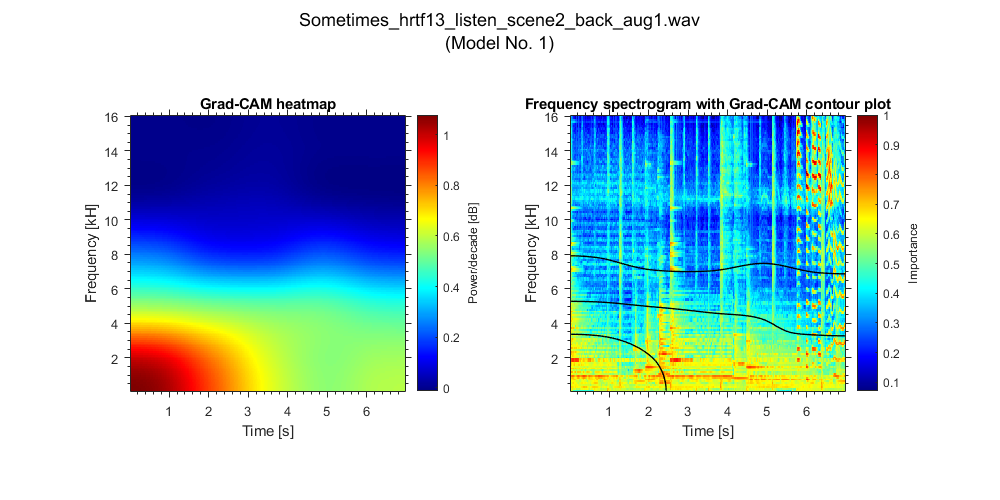

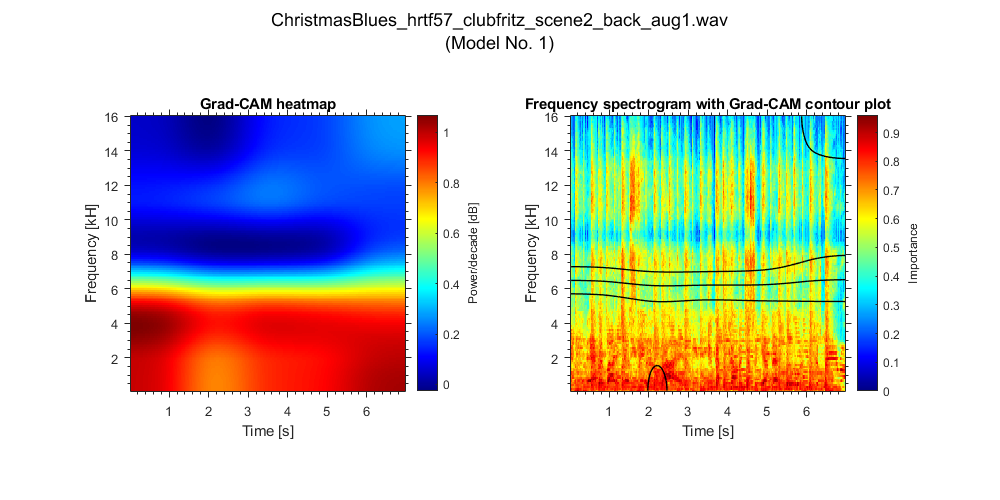

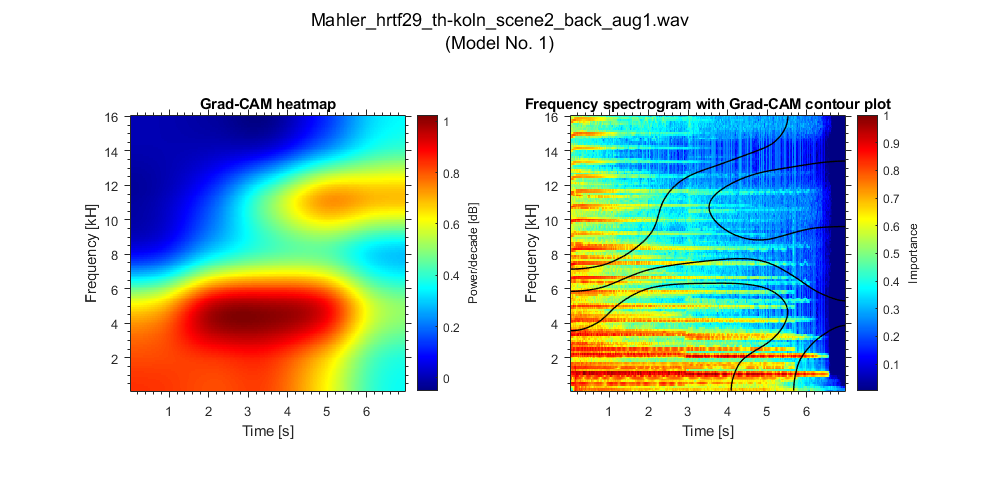

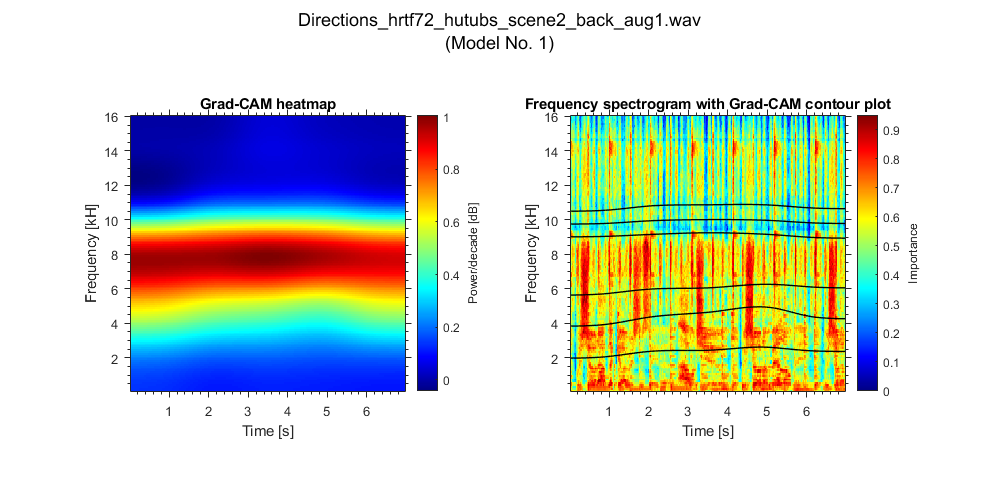

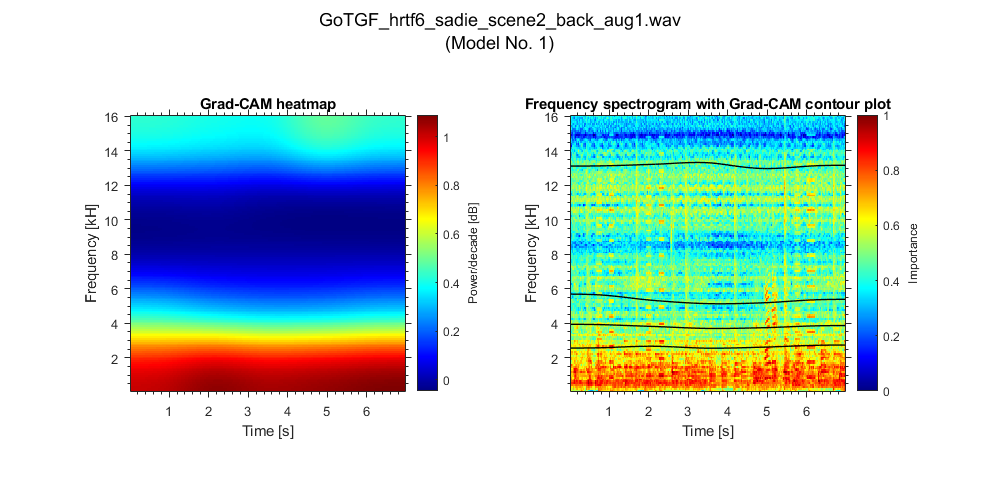

figure('Position', [0 0 1000 500])
rng(111)
selectedSpecgramIndices = randi(dslen, 1, 5);

for iSpecgram = selectedSpecgramIndices
    sampleSpecgrams = h5read(inputSpecgramsFile, '/data', ...
        [1, 1, 1, iSpecgram], [inputSize, 1]);
    scoreMap = customGradCam(currentNetwork, sampleSpecgrams, ...
        dslabels(iSpecgram) + 1);
    
    specNames = {'left', 'right', 'sum', 'difference'};    
    
    figure('Position', [0 0 1000 500])
    sgtitle({dsfilenames(iSpecgram), sprintf('(Model No. %d)', iNetwork)},  'Interpreter', 'none'); 
    
    subplot(1, 2, 1);
    imagesc(timeValues, freqValues / 1000, scoreMap');
    colormap jet; 
    axis xy;  
    pbaspect([1 1 1])
    title(['Grad-CAM heatmap'])
    xlabel('Time [s]')
    ylabel('Frequency [kH]')
    ylabel(colorbar, 'Power/decade [dB]')
    set(gca, 'XMinorTick', 'on', 'YMinorTick', 'on', ...
        'TickDir', 'out', 'TickLength', [0.02 0.025])
    
    subplot(1, 2, 2);
    imagesc(timeValues, freqValues / 1000, sampleSpecgrams(:, :, 1)'); 
    colormap jet; 
    axis xy;  
    pbaspect([1 1 1])
    title(['Frequency spectrogram with Grad-CAM contour plot'])
    xlabel('Time [s]')
    ylabel('Frequency [kH]')
    ylabel(colorbar, 'Importance')
    set(gca, 'XMinorTick', 'on', 'YMinorTick', 'on', ...
        'TickDir', 'out', 'TickLength', [0.02 0.025])
    
    hold on
    [C, h] = imcontour(timeValues, freqValues / 1000, scoreMap', 3, 'k');
    h.LineWidth = 1;
    
    save(sprintf('gradCAM_importance_curve_hrtf_p%d_%d', ii, iNetwork), 'meanSpectrum', '-v7.3');
end

function cam = customGradCam(currentNetwork, input, label)
    cam = gradCAM(currentNetwork, input, label,... 
        'FeatureLayer', 'relu_5');
end
